%**************************************************************************
% AUTHOR: Brayan Espinoza 17/10/2024
% DESCRIPTION: 
% This program performs the simulation of an adaptive PID control algorithm 
% for a 2DOF telescope modeled as a 2DOF robotic arm using Lagrange
% equations.
% IMPORTANT: 
% The telescope is modeled without taking into consideration the actuators
% and sensor errors, so the required torque is used as input.
%
% *************************************************************************

%%% Simulation Parameters
m1  = 7;     % Mass of the first link (kg)
m2  = 10;    % Mass of the second link (kg)
l1  = 0.2;   % Length of the first link (m)
l2  = 0.8;   % Length of the second link (m)
r1  = 0.20;  % Radius or distance from the first joint to the center of mass (m)
r2  = 0.15;  % Radius or distance from the second joint to the center of mass (m)
g   = 9.81;  % Gravitational acceleration (m/s^2)

%%%%% New rotation center
cd  = [0,0,-l2/2]';  % Coordinate of the new rotation center (for example, at the middle of link 2)

theta1 = 0;  % Initial angle for the first joint (azimuth)
theta2 = 0;  % Initial angle for the second joint (elevation)

%% DH Parameters (Denavit-Hartenberg)
% DH parameters describe the joint transformations for a robotic system.
% The parameters are in the form [A, alpha, d, theta]:
% A = link length, alpha = link twist, d = link offset, theta = joint angle
dhparams = [0   pi/2  l1 theta1;  % Parameters for the first link (azimuth)
            l2  0     0 theta2];  % Parameters for the second link (elevation)

% Create a rigid body tree structure for the telescope with 2 bodies (links).
telescope = rigidBodyTree('DataFormat', 'column', 'MaxNumBodies', 2);

% Initialize cell arrays for bodies and joints (since we have two bodies/links).
bodies = cell(2,1);
joints = cell(2,1);

% Loop to define each body and its corresponding joint
for i = 1:2
    bodies{i} = rigidBody(['body' num2str(i)]);  % Create a rigid body for the i-th link
    joints{i} = rigidBodyJoint(['jnt' num2str(i)], "revolute");  % Create a revolute joint for rotation
    setFixedTransform(joints{i}, dhparams(i,:), "dh");  % Set the fixed transformation based on DH parameters
    bodies{i}.Joint = joints{i};  % Assign the joint to the body
    
    % Add bodies to the telescope rigid body tree
    if i == 1
        % Add the first body to the base of the rigid body tree
        addBody(telescope, bodies{i}, "base");
    else
        % Add the current body to the previous body in the tree
        addBody(telescope, bodies{i}, bodies{i-1}.Name);
    end
end

% Show details of the rigid body tree model (structure of the telescope)
showdetails(telescope);

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   
--------------------


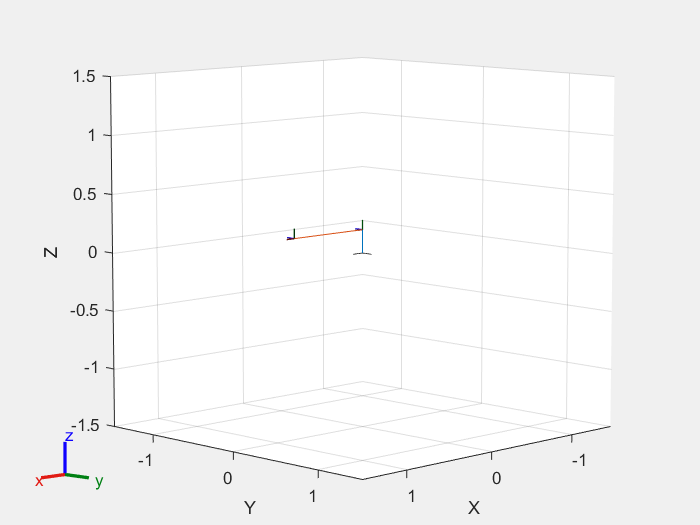

figure(Name="Telescope Model")
show(telescope,[0,0]');

%%figure(Name="Interactive GUI")
%%gui = interactiveRigidBodyTree(telescope,MarkerScaleFactor=0.5);

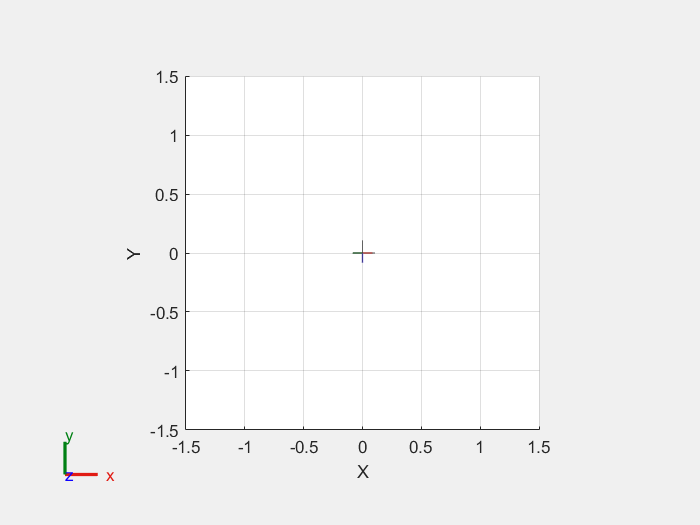

% Create a new figure for visualization
figure

% Show the telescope model using the 'show' function
% The joint configuration is specified as [0, pi/2]', where:
%  - 0 is the initial angle for the first joint (azimuth)
%  - pi/2 is the initial angle for the second joint (elevation)
show(telescope, [0, pi/2]');

% Set the view of the plot to 2D, which is useful for displaying azimuth and elevation
view(2)

% Count the number of time steps (this assumes you have a time output structure 'out' with field 'tout')
count = length(out.tout);

% Get the current axes handle and set the projection to orthographic
% Orthographic projection removes perspective distortion, which is better for technical visualizations
ax = gca;
ax.Projection = 'orthographic';

% Hold on to the current figure so that additional plotting commands don't overwrite the existing plot
hold on